# Specify a Stylesheet as a `StylesheetSourceDocument` Object

Suppose that you want to customize a stylesheet for a transformation, but do not want to modify the file that contains the stylesheet. You can read the stylesheet file into a DOM document, modify the style in the document, and then use the document as the stylesheet for the transformation. Specify the stylesheet as a `matlab.io.xml.transform.StylesheetSourceDocument` object. 

This example transforms the XML markup for countries and their capital cities into an HTML table. The original XSL file specifies a table with the default color, black. The example parses the XSL from the file into a `matlab.io.xml.dom.Document` object, modifies the style to make the table green, and passes the `Document` object to the transformation as a `matlab.io.xml.transform.StylesheetSourceDocument` object.

The example uses these files:

- capitals.xml

- capitals.xsl

Parse a stylesheet file into a `matlab.io.xml.dom.Document` object.

import matlab.io.xml.dom.*
import matlab.io.xml.transform.*
import matlab.io.xml.xpath.*

ssDoc = parseFile(Parser,"capitals.xsl");

Find the table element and add a style attribute that specifies the color green.

tableElem = evaluate(Evaluator,"//table",ssDoc);
styleAttr = createAttribute(ssDoc,"style");
setValue(styleAttr,"color:green");
setAttributeNode(tableElem,styleAttr);

Create a `StylesheetSourceDocument` object, `stylesheetObj`, that contains the `Document` object with the XSL markup to use for the transformation.

stylesheetObj = StylesheetSourceDocument(ssDoc);

Perform the transformation and provide `stylesheetObj` as the stylesheet, `capitals.xml` as the source XML, and `capitals.html` as the name of the output file.

transform(Transformer,"capitals.xml",stylesheetObj,"capitals.html");

Open capitals.html in a browser.

web("capitals.html")

Here is the HTML table:

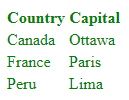

*Copyright 2020 The MathWorks, Inc.*